G = get_full_graph(fullfile("additional_Files", "building_collider_list.csv"), true);

folder_path = fullfile("F:\big-data\vr_data\Data\preprocessing-pipeline\noises-vs-gazes");
p_table = create_participant_table(folder_path);

gaze_full_data = get_gaze_data(folder_path, p_table.PID', '_gazes_data_WB.mat');

% hardcoded
excluded_parts = [4004, 4025, 4028, 4011];

query = p_table.category == "control";
control_parts = p_table(query, :);

#### Fixation Time filtering

- Fixation time mean (with and without correction)

- Fixation time for landmarks

- Fixation time including inside/outside (with and without correction)

- Number of Fixations

% remove noData newSession NH
% exclude participants
removed_clusters = ["noData", "newSession", "NH"];
query = ~any(string(gaze_full_data.hitObjectColliderName) == removed_clusters, 2);

clean_gaze_full_data = gaze_full_data(query, :);
query = ~any(clean_gaze_full_data.PID == excluded_parts, 2);
clean_gaze_full_data = clean_gaze_full_data(query, :);


% total fixation
no_fixation = groupsummary(clean_gaze_full_data, "PID");

% sum of cluster duration
collider_sum_gaze = groupsummary(clean_gaze_full_data, {'PID', 'hitObjectColliderName'}, 'sum', 'clusterDuration');

query = ~any(collider_sum_gaze.PID == excluded_parts, 2);
excluded_sum_gaze = collider_sum_gaze(query, :);

% only participants in control group
query = any(excluded_sum_gaze.PID == control_parts.PID', 2);
excluded_control_sum_gaze = excluded_sum_gaze(query,:);

% clean gaze data joined with participant table
gaze_full_group = join(clean_gaze_full_data, p_table);

#### Common Building Filter

the buildings that are seen by control participants are considered as common buildings.

common_buildings = G.Nodes.Name;
cur_parts = unique(excluded_control_sum_gaze.PID);

for control = cur_parts'
    query = excluded_control_sum_gaze.PID == control;
    cur_excluded_control_sum_gaze = excluded_control_sum_gaze(query, :)
    cur_buildings = cur_excluded_control_sum_gaze.hitObjectColliderName;
    common_buildings = intersect(common_buildings, cur_buildings);
end

cur_excluded_control_sum_gaze = 77×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4007      {'Building_100'}            8              3008.4       
    4007      {'Building_101'}            9              3387.1       
    4007      {'Building_102'}            3              1501.1       
    4007      {'Building_109'}            1              399.32       
    4007      {'Building_139'}            2              1402.5       
    4007      {'Building_140'}            8              3624.7       
    4007      {'Building_141'}            1               476.5       
    4007      {'Building_144'}            3              1187.6       
    4007      {'Building_145'}           15              7112.5       
    4007      {'Building_146'}         

cur_excluded_control_sum_gaze = 76×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4010      {'Building_100'}           10                5279       
    4010      {'Building_101'}           29               17097       
    4010      {'Building_102'}           12              6676.6       
    4010      {'Building_108'}            1              311.17       
    4010      {'Building_109'}            5                2865       
    4010      {'Building_141'}            2              664.01       
    4010      {'Building_143'}            1              377.74       
    4010      {'Building_144'}            1              420.46       
    4010      {'Building_145'}            6              2794.9       
    4010      {'Building_146'}         

cur_excluded_control_sum_gaze = 85×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4013      {'Building_100'}            9              3424.6       
    4013      {'Building_101'}           15                6104       
    4013      {'Building_102'}            7              3328.5       
    4013      {'Building_137'}            1              433.59       
    4013      {'Building_139'}            4              1404.1       
    4013      {'Building_140'}           12              5363.2       
    4013      {'Building_141'}            3                1634       
    4013      {'Building_142'}            5              1598.1       
    4013      {'Building_143'}            3              1065.7       
    4013      {'Building_144'}         

cur_excluded_control_sum_gaze = 73×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4016      {'Building_100'}           26               11980       
    4016      {'Building_101'}           23               10996       
    4016      {'Building_102'}           37               26767       
    4016      {'Building_140'}            2              866.17       
    4016      {'Building_141'}            4              1956.9       
    4016      {'Building_143'}            1               444.3       
    4016      {'Building_144'}            7              2457.4       
    4016      {'Building_145'}            7              2377.4       
    4016      {'Building_147'}           14              5868.7       
    4016      {'Building_148'}         

cur_excluded_control_sum_gaze = 91×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4019      {'Building_100'}            3              964.94       
    4019      {'Building_101'}            9              4211.4       
    4019      {'Building_102'}            7              3208.2       
    4019      {'Building_103'}            1              410.02       
    4019      {'Building_108'}            1              365.87       
    4019      {'Building_109'}            2              799.38       
    4019      {'Building_139'}            3              1020.8       
    4019      {'Building_140'}            1              556.57       
    4019      {'Building_141'}            6              1812.2       
    4019      {'Building_142'}         

cur_excluded_control_sum_gaze = 86×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4022      {'Building_100'}           15              5258.1       
    4022      {'Building_101'}            8                3455       
    4022      {'Building_102'}           10              4208.6       
    4022      {'Building_103'}            1               410.9       
    4022      {'Building_108'}            1              299.77       
    4022      {'Building_139'}            5                1847       
    4022      {'Building_140'}            5              3420.4       
    4022      {'Building_141'}            4              1514.2       
    4022      {'Building_142'}            1              2294.9       
    4022      {'Building_143'}         

cur_excluded_control_sum_gaze = 80×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4031      {'Building_100'}           12              4479.4       
    4031      {'Building_101'}           17              6876.8       
    4031      {'Building_102'}           12              5948.6       
    4031      {'Building_108'}            1              422.69       
    4031      {'Building_139'}            1              409.97       
    4031      {'Building_140'}            8              4078.6       
    4031      {'Building_141'}            7              3499.7       
    4031      {'Building_143'}            2               844.1       
    4031      {'Building_144'}           15              9043.9       
    4031      {'Building_145'}         

cur_excluded_control_sum_gaze = 82×4 table
    PID     hitObjectColliderName    GroupCount    sum_clusterDuration
    ____    _____________________    __________    ___________________

    4034      {'Building_100'}           10              3598.6       
    4034      {'Building_101'}            6              3432.3       
    4034      {'Building_102'}           12               10551       
    4034      {'Building_131'}            3               890.1       
    4034      {'Building_137'}            1              277.63       
    4034      {'Building_139'}            1              377.34       
    4034      {'Building_140'}            9              4132.8       
    4034      {'Building_141'}            9              5010.2       
    4034      {'Building_142'}            1              656.19       
    4034      {'Building_144'}         

% Common Building := buildings that are seen all of the control
% participants
common_buildings

common_buildings = 57×1 cell array
    {'Building_100'}
    {'Building_101'}
    {'Building_102'}
    {'Building_141'}
    {'Building_144'}
    {'Building_145'}
    {'Building_147'}
    {'Building_148'}
    {'Building_149'}
    {'Building_150'}
    {'Building_152'}
    {'Building_153'}
    {'Building_154'}
    {'Building_155'}
    {'Building_156'}
    {'Building_157'}
    {'Building_158'}
    {'Building_159'}
    {'Building_160'}
    {'Building_161'}
    {'Building_162'}
    {'Building_163'}
    {'Building_164'}
    {'Building_165'}
    {'Building_166'}
    {'Building_167'}
    {'Building_168'}
    {'Building_169'}
    {'Building_170'}
    {'Building_171'}


query = any(string(excluded_control_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
common_buildings_control_sum_gaze = excluded_control_sum_gaze(query, :);

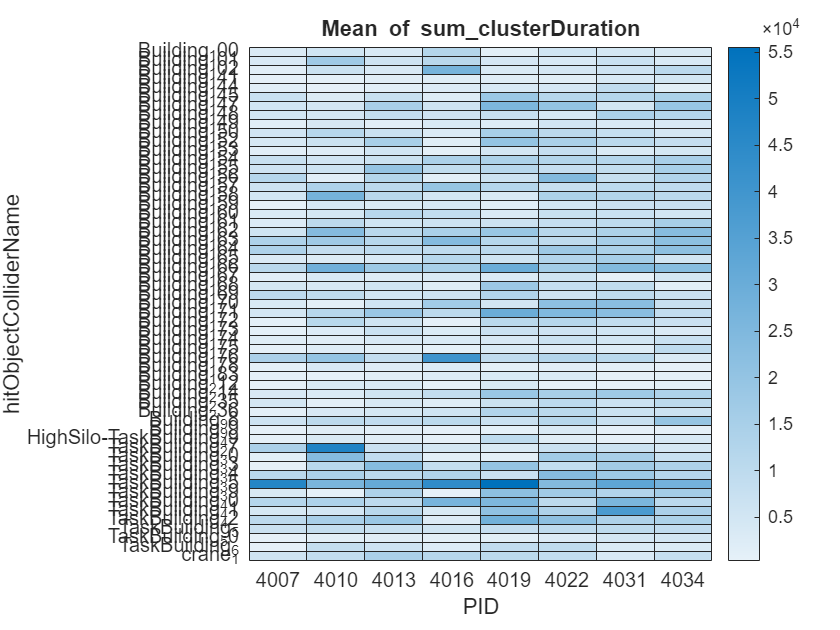

% heatmap of control participants only for sanity check
heatmap(common_buildings_control_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration")

% reorder participants to have a good heatmap
unique_parts = unique(excluded_sum_gaze.PID);

full_central_parts = p_table(p_table.category == "central", :);
central_parts = intersect(unique_parts, full_central_parts.PID);

full_perip_parts = p_table(p_table.category == "peripheral", :);
perip_parts = intersect(unique_parts, full_perip_parts.PID);

control_parts = intersect(unique_parts, control_parts.PID);

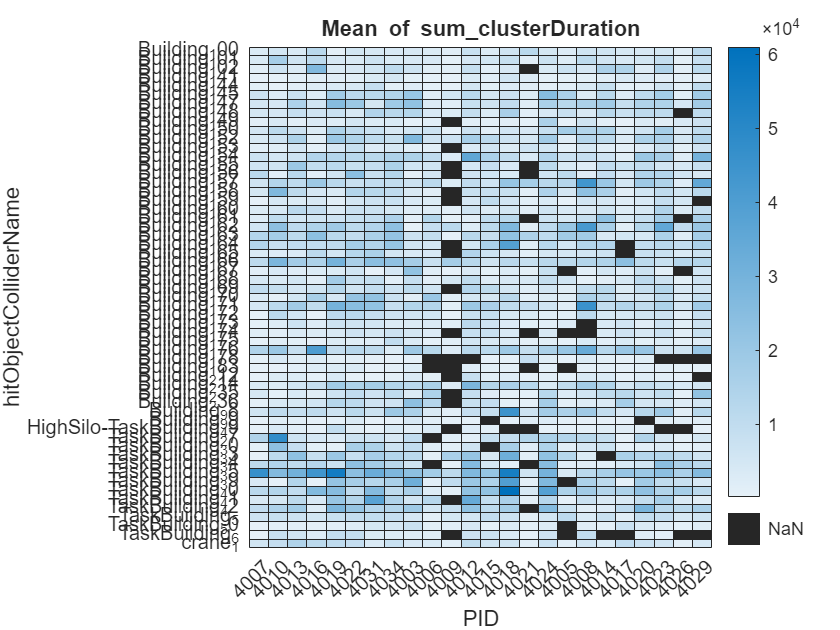

query = any(string(excluded_sum_gaze.hitObjectColliderName) == string(common_buildings)', 2);
commong_buildings_excluded_sum_gaze = excluded_sum_gaze(query, :);
% 
h = heatmap(commong_buildings_excluded_sum_gaze, "PID", "hitObjectColliderName", "ColorVariable", "sum_clusterDuration");
h.XDisplayData = [control_parts; perip_parts; central_parts];

#### Node Data Table

folder_path = fullfile("F:\big-data\vr_data\Data\preprocessing-pipeline\graphs");
graph_table = create_graph_table(folder_path);

% hardcoded excluded parts defined above
query = ~any(graph_table.PID == excluded_parts, 2);
excluded_graph_table = graph_table(query, :);

% summary connectivity table is the one with full graph to normalize
% everything across all subjects.
summary_connectivity_table = groupsummary(excluded_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

% excluding buildings that are not considered by participants
% the rationale might be that participants are not aware of ROI in the city
% This might lead them to focus on the things by which they already got
% attended.
std_graph_table = excluded_graph_table(excluded_graph_table.connections > 0, :);
standard_summary_connectivity_table = groupsummary(std_graph_table, {'PID'}, {'mean', 'std'}, 'connections');

analyzed_p_data = [control_parts; perip_parts; central_parts];
[r, ~] = find(p_table.PID == analyzed_p_data');
categories = p_table.category(r);

#### Run ANOVA for Connectivity

[r, ~] = find(standard_summary_connectivity_table.PID == analyzed_p_data');

Normality Tests:
Group central: p = 0.3954, Normal
Group control: p = 0.3455, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


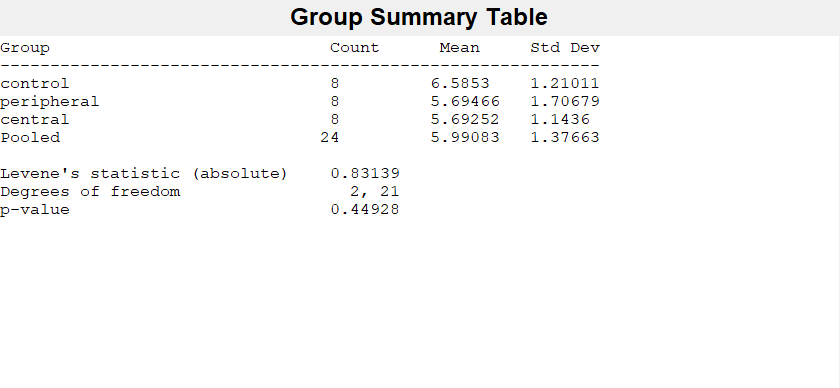

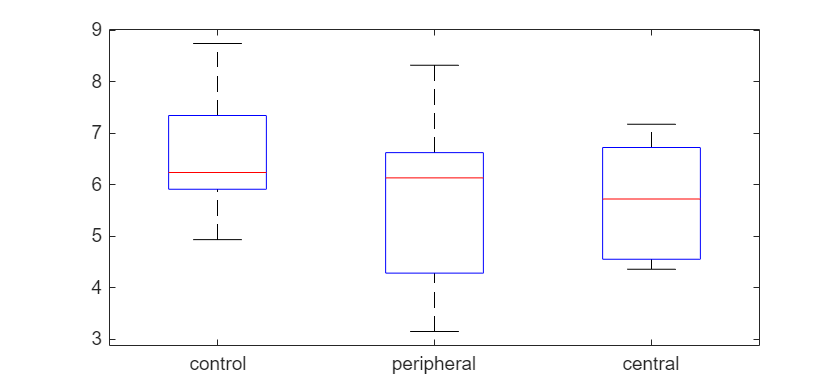

Levene test: p = 0.4493, Equal variances

ANOVA Results:


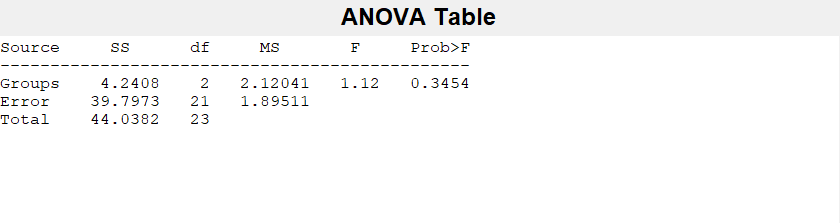

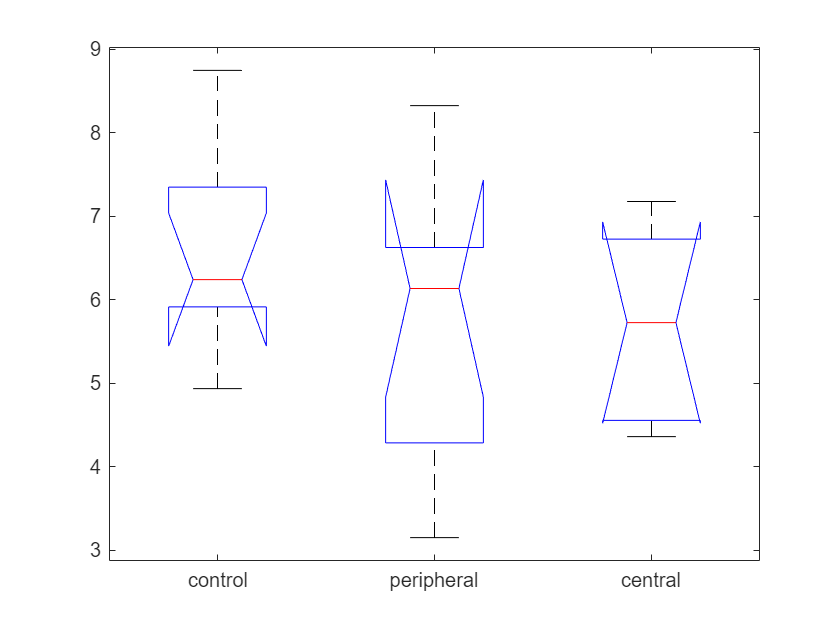

% without correction for mean connections
connectivity_data = standard_summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

Normality Tests:
Group central: p = 0.1770, Normal


Group control: p = 0.5000, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


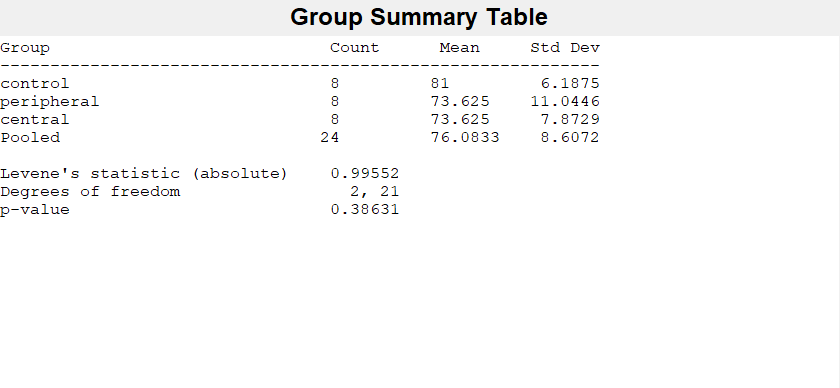

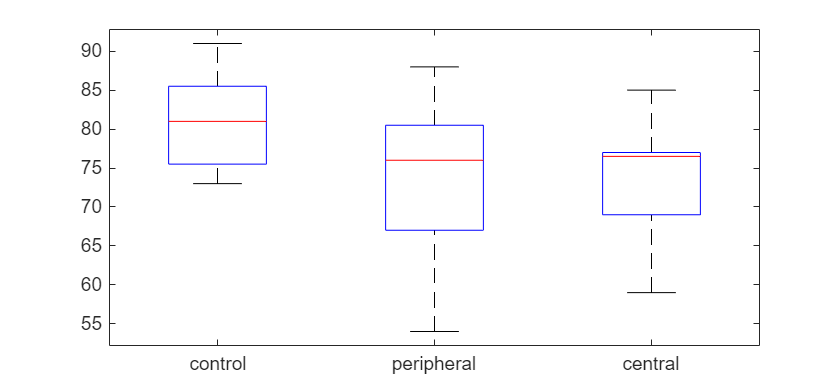

Levene test: p = 0.3863, Equal variances

ANOVA Results:


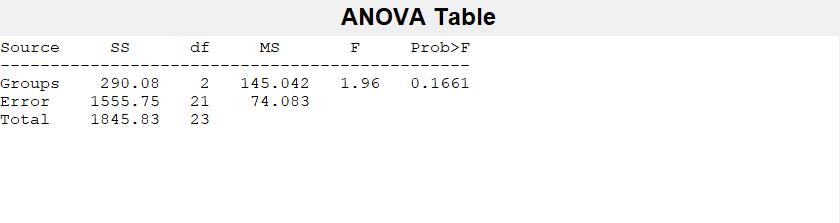

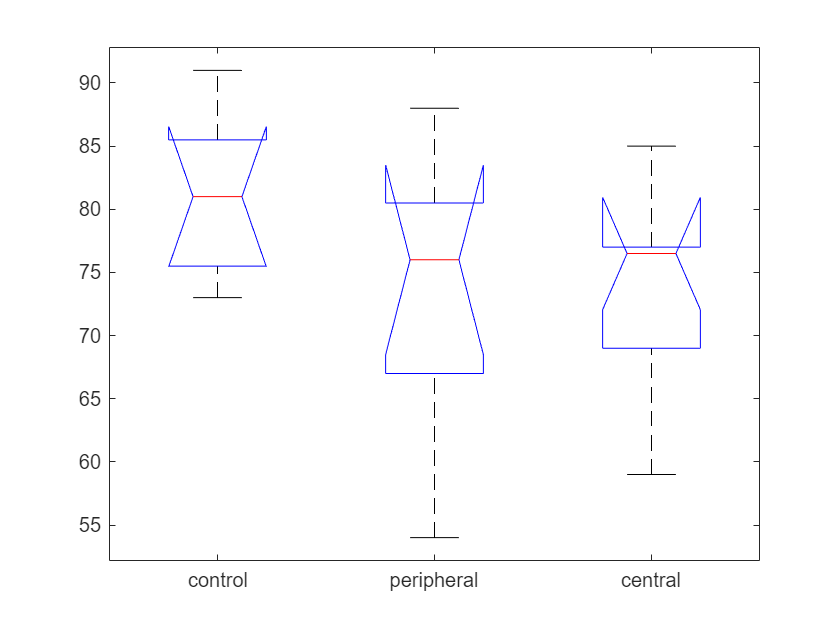

% building count
count_data = standard_summary_connectivity_table.GroupCount(r);
run_anova(count_data, categories);

Normality Tests:


Group central: p = 0.5000, Normal
Group control: p = 0.1046, Normal


Group peripheral: p = 0.5000, Normal

Homogeneity of Variance Test:


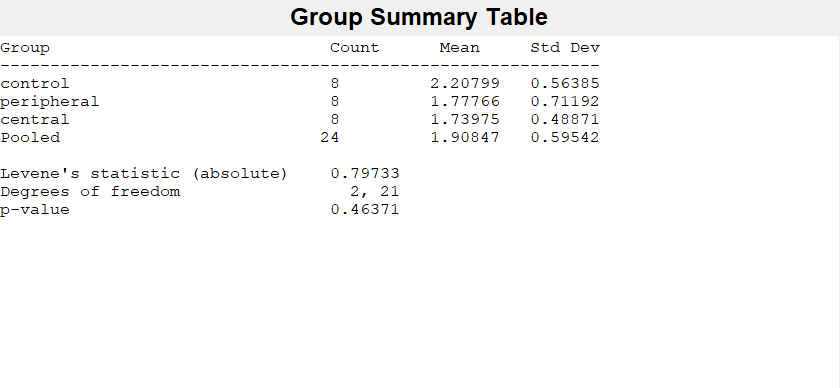

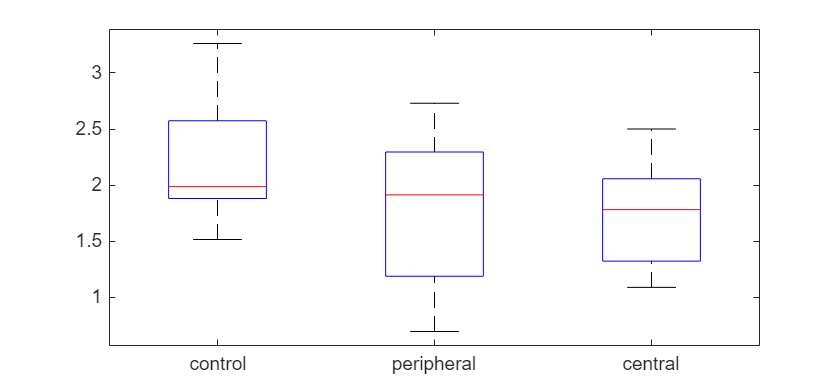

Levene test: p = 0.4637, Equal variances

ANOVA Results:


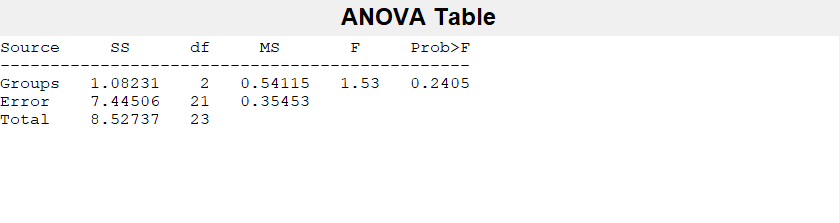

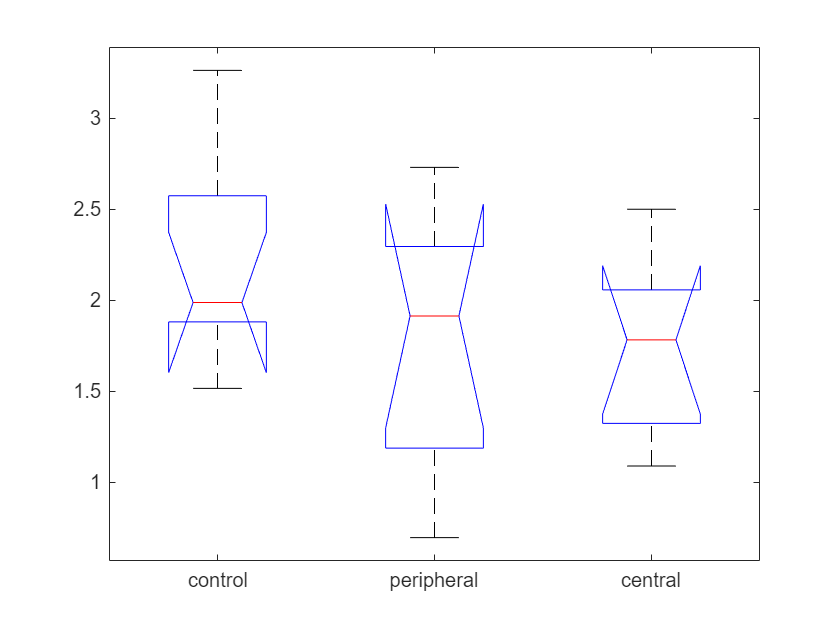

% with correction for mean connections
connectivity_data = summary_connectivity_table.mean_connections(r);
run_anova(connectivity_data, categories);

#### Run ANOVA for Fixation Related Measure

Normality Tests:
Group central: p = 0.0931, Normal


Group control: p = 0.5000, Normal
Group peripheral: p = 0.2969, Normal

Homogeneity of Variance Test:


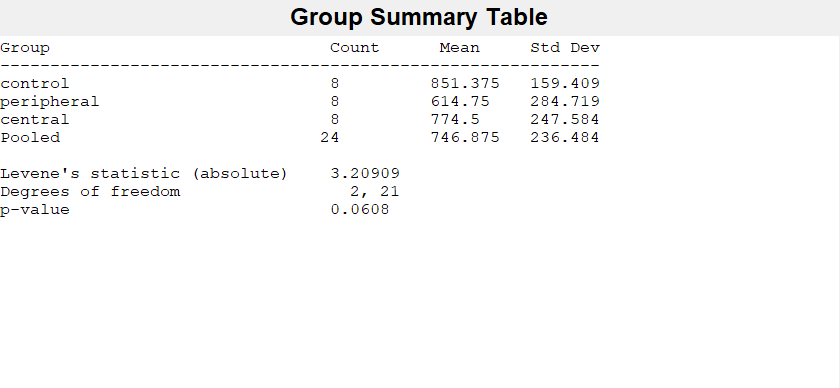

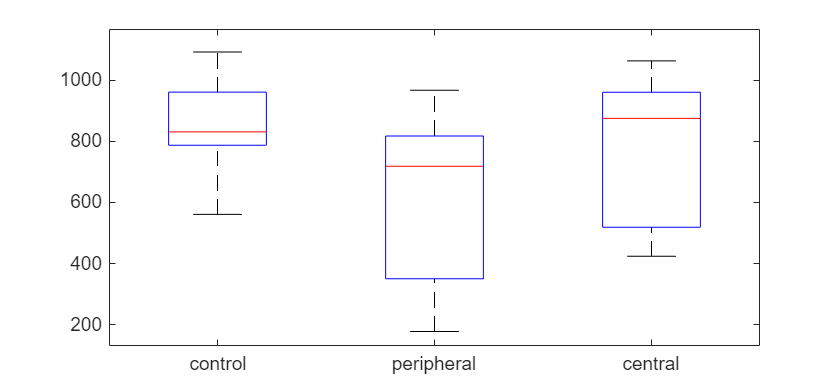

Levene test: p = 0.0608, Equal variances

ANOVA Results:


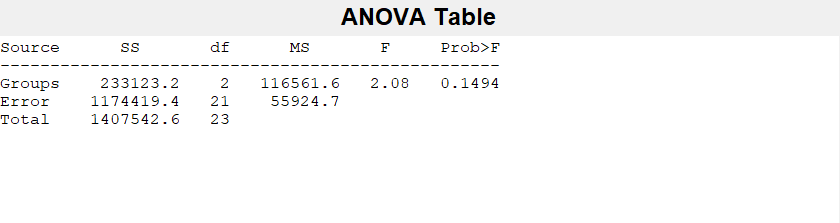

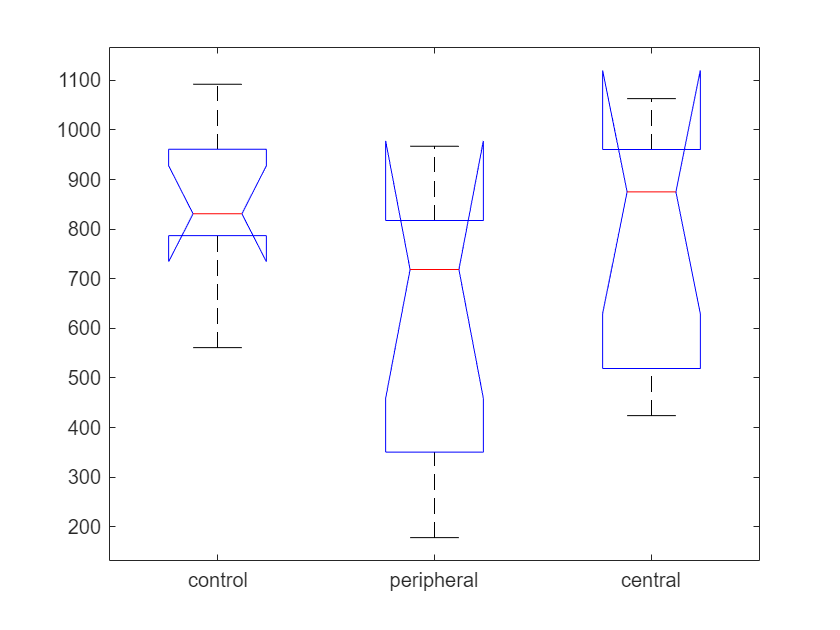

% check # of fixation
[r, ~] = find(no_fixation.PID == analyzed_p_data');

data = no_fixation.GroupCount(r);
run_anova(data, categories);

#### Run LLM for Fixation Related Measure

Residuals are NOT normally distributed (p < 0.05). Consider transforming the data.


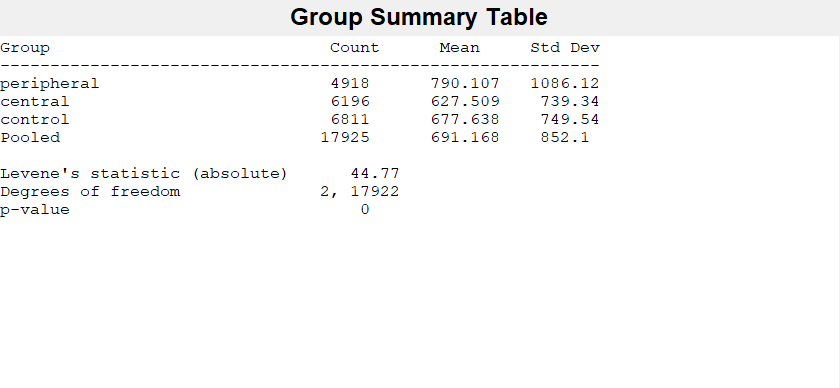

Variances are NOT equal across groups (p < 0.05). Consider data transformation or using fitglme.
Visualizing potential outliers with a boxplot...
Checking for multicollinearity between predictors...


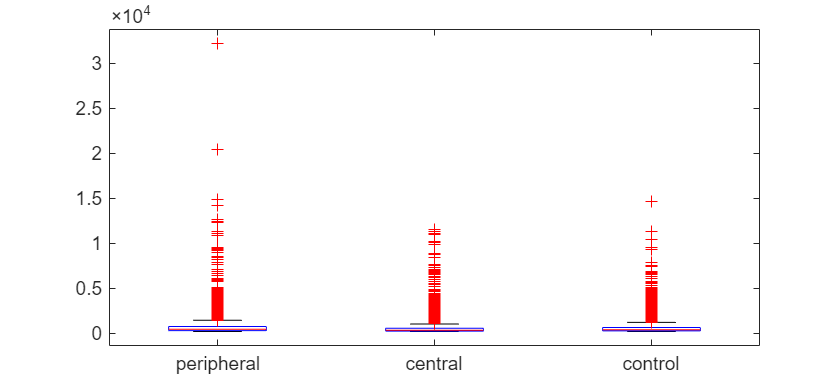

Variance Inflation Factors (VIF):
   1.0e+14 *

    8.2464    8.5896    7.2587

Checking if random effects significantly improve the model...
Random effects significantly improve the model (p < 0.05).
Pre-tests completed. You can now proceed to fit the Linear Mixed Model (LMM).


pre_lmm_pipeline(gaze_full_group, "clusterDuration", "category", "PID");

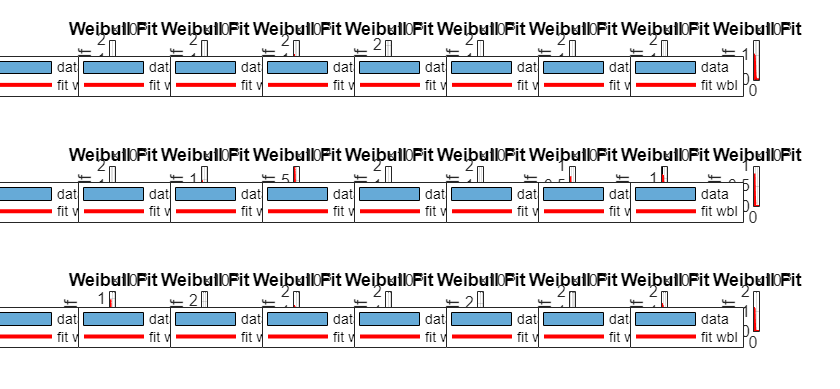

gaze_full_group.logDuration = log(gaze_full_group.clusterDuration);
tiledlayout(3, 8);
for dummy_p = analyzed_p_data'
    nexttile;
    cur_data = gaze_full_group(gaze_full_group.PID == dummy_p, :);
    fit_normal(cur_data.clusterDuration);
end